# Cheon-Kim-Kim-Song (CKKS)

CCKS allows us to perform computations on vectors of complex (and real) values. CKKS uses approximate arithmetic instead of exact arithmetic, in the sense that once we finish computation we might get a slightly different result than if we did the computation directly. This means that if you encrypt 2 and 3, add their ciphertexts, and decrypt you might get something like 4.99 or 5.01 but not 5.

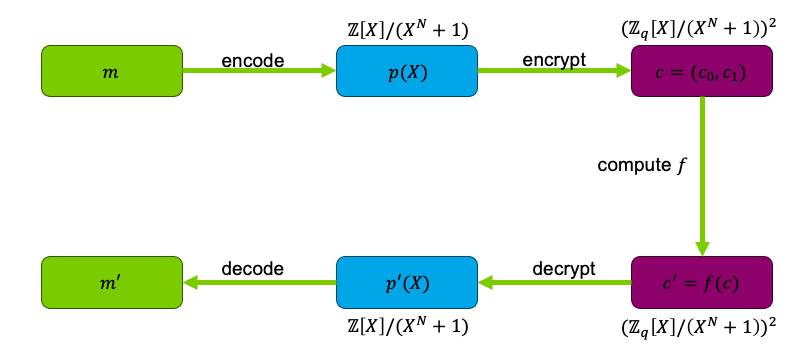

The figure above illustrates a high-level view of CKKS.  The message $m$, a vector of values that we wish to perform computations on, is first envoded into $p(X)$, which is the *plaintext polynomial*.  Thereafter, it is encrypted using a public key.

The resulting ciphertext, $c$, consists of a couple of polynomials whose properties enable us to perform operations on it such as addition, multiplication, and rotation.

## Encoding in CKKS

CKKS exploits the rich structure of integer polynomial rings for its plaintext and ciphertext spaces.  However, data typically comes in the form of vectors rather than polynomials.  Therefore, it is necessary to encode our input $z \in \mathbb{C}^N/2$ into a polynomial $m(X) \in \mathbb{Z}[X]/(X^N + 1)$.  

The degree of our polynomial degree modulus is defined by $N$, which is a power of 2.  The $m$-th cyclotomic polynomial (note that $M = 2N$) by $\Phi_M(X) = X^N + 1$.  The plaintext space will be the polynomial ring $\mathcal{R} = \mathbb{Z}[X]/(X^N + 1)$.  Let $\xi_M =e^{\frac{2i\pi }{M}}$be the $M$-th root of unity.

### Vanilla Encoding

We first demonstrate how to encode a vector into a polynomial and how the computation performed on the polynomial will be reflected in the underlying vector:$z \in \mathbb{C}^N$ into a polynomial $m(X) \in \mathbb{C}[X]/(X^N + 1)$. 

To do so, we use the canonical embedding $\sigma$: $\mathbb{C}[X]/(X^N + 1) \rightarrow \mathbb{C}^N$.  This embedding decodes and encodes our vectors and it is important to note that $\sigma$ defines an isomorpism. This means that any vector will be uniquely encoded into its corresponding polynomial, and vice-versa.

Decoding a polynomial $m(X)$ into a vector $z$ involves evaluating the polynomial on certain values, which will be the roots of the cyclotomic polynomial $\Phi_M(X) = X^N + 1$. Those $N$ roots are: $\xi, \xi^3,\dots,\xi^{2N-1}$.

This implies decoding a polynomial $m(X)$ as $\sigma(m) = (m(\xi), m(\xi^3), \dots, m(\xi^{2N-1})) \in \mathbb{C}^N$.

The non-trivial part is the encoding of a vector $z \in \mathbb{C}^N$ into the corresponding polynomial due to computing the inverse $\sigma^{-1}$.  As such, this requires finding a polynomial $m(X) = \sum_{i=0}^{N-1} \alpha_iX^i \in \mathbb{C}[X]/(X^N +1)$ given a vector such that $\sigma(m) = (m(\xi), m(\xi^3), \dots, m(\xi^{2N-1})) = (z_1, \dots, z_N)$.

Consider the following system: $\sum_{j=0}^{N-1} \alpha_j(\xi^{2i-1})^j = z_i$ for $i = 1,\dots,N$.  This can be viewed as a linear equation $A\alpha = z$, where $A$ is the Vandermonde matrix of the $(\xi^{2i-1})_{i=1,\dots,N}$, $\alpha$ is the vector of polynomial coefficients, and $z$ is the vector we want to encode.  Therefore, we have $\alpha = A^{-1}z$ and that $\sigma^{-1}(z) = \sum_{i-0}^{N-1} \alpha_iX^i \in \mathbb{C}[X]/(X^N + 1)$.

clear all
close all
clc

% m-th cyclotomic polynomial
M = 8;
N = floorDiv(M,2);

% set xi which will be used for computations in this example
xi = exp(2*pi*j/M);

b = [1 2 3 4];

% encode vector and print
p = sigma_inverse(b,xi,M);
% print the coefficients as symbolic polynomial
% poly2sym(flip(p))
% decode/extract vector from polynomial
b_recon = sigma(p,xi,M)

b_recon =    1.0000 - 0.0000i   2.0000 + 0.0000i   3.0000 - 0.0000i   4.0000 + 0.0000i


The canonical embedding $\sigma$ contains homomorphic properties, so addition and multiplication on polynomials will result in coefficient wise addition and multiplication on the encodeded vectors.  This properties is due to the fact that $X^N + 1 = 0$ and $\xi^N + 1 = 0$.

m1 = [1 2 3 4];
m2 = [1 -2 3 -4];

p1 = sigma_inverse(m1,xi,M);
p2 = sigma_inverse(m2,xi,M);

p_add = p1 + p2;
m_add = sigma(p_add,xi,M)

m_add =    2.0000 - 0.0000i  -0.0000 + 0.0000i   6.0000 - 0.0000i   0.0000 + 0.0000i


For multiplication, we may have terms whose degree is higher than $N$, thus we will need to perform a modulo operaiton using $X^N + 1$.

poly_mod = gen_polymod(N);
poly2sym(poly_mod)

$$ans = x^{4}+1$$

[b,r] = deconv(conv(p1,p2,'full'),poly_mod)

b =   -1.2500 - 0.0000i
  -1.7678 - 0.3536i
   0.0000 - 7.0000i


r =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   3.5355 - 0.7071i
   2.5000 + 0.0000i
   3.5355 + 0.7071i
  -0.0000 + 7.5000i


m_mult = sigma(r,xi,M)

m_mult =    1.0000 + 0.0000i  -4.0000 + 0.0000i   9.0000 - 0.0000i -16.0000 + 0.0000i


As shown by this example, the simple encoder and decoder works as expected with one-to-one mapping between vectors and polynomials and demonstrates its homomorphic properties.  What we need our encoder to do is map polynomials to $\mathbb{Z}[X]/(X^N + 1)$ to exploit all the properties of integer polynomial rings, thus we need an encoder that outputs polynomials with integer coefficients and not complex coefficients.

## Full Encoding and Decoding

In the previous section, we demonstrated that in order to implement the CKKS encryption scheme for computation on encrypted complex vectors, we must first build an encoder and a decoder to transform our complex vectors into polynomials.

This encoder-decoder step is necessary because the encryption, decryption, and other mechanisms work on polynomial rings. Therefore, it is necessary to have a way to transform our vectors of real values into polynomials.

Nevertheless, because we want our encoder to output polynomials in $\mathbb{Z}[X]/(X^N + 1)$ so as to exploit the structure of polynomial integer rings, we need to modify this first vanilla encoder to be able to output polynomials of the right ring. The difference now is that the plaintext space of the encoded polynomial is now $\mathcal{R} = \mathbb{Z}[X]/(X^N + 1)$ instead of $\mathbb{C}[X]/(X^N + 1)$.  This yields encoded polynomials that contain integer coefficients. 

clear all
close all
clc

% NOTE: create environment variable
M = 2^4; % 2^(data entries)

N = floorDiv(M,4);
xi = exp(2*pi*j/M);
basis = create_sigma_R_basis(xi,M);
scale = 2^18;

This defines our basis $\sigma(1), \sigma(X), \sigma(X^2), \sigma(X^3)$. Next, we will check that the elements of $\mathbb{Z}\{\sigma(1),\sigma(X),\sigma(X^2),\sigma(X^3)\}$ are encoded as integer polynomials.

% vector whose coordinates are (1,1,1,1) in the lattice basis
% coord = [1;1;1;1];
% 
% b = basis.'*coord
% check encoding of polynomia;
% p = sigma_inverse(b',xi,M)

Trying out the encoder and decoder:

z = [3.65 2.35 9.42 0.87]; % data we want to encrypt
p = encode(z,basis,xi,M,scale); % show with poly2sim
z_decode = decode(p,scale,xi,M)

z_decode =    3.6500 - 0.0000i   2.3500 - 0.0000i   9.4200 + 0.0000i   0.8700 + 0.0000i


z_real = real(z_decode)

z_real =     3.6500    2.3500    9.4200    0.8700


## Ring Learning with Errors

The foundation of CKKS is the Learning With Error (LWE) problem.  However,  LWE contains a secret key size of $\mathcal{O}(n)$ resulting in the public key of size $\mathcal{O}(n^2)$ due to the matrix $A$.  Therefore, computations will also require $\mathcal{O}(n^2)$ operations. Because $n$ will dictate the security of the scheme, if we use LWE to construct our scheme, it will be too inefficient in practice as the $\mathcal{O}(n^2)$ size of keys and complexity will make it too impractical.

Instead of working with vectors in $\mathbb{Z}_q^n$, the Ring-LWE (RLWE) scheme works on polynomials in $\mathbb{Z}_q[X]/(X^N + 1)$.  Now, we randomly sample $a$, $s$, and $e$ from $\mathbb{Z}_q[X]/(X^N + 1)$, where $a$ is sampled uniformly, $s$ is a small secret polynomial, and $e$ is a small noisy polynomial.  RLWE has two main advantages:

- The key size is no longer quadratic but linear, as we now ouput the public key $k_{pub} = (-a \cdot s + e, a)$, where $a \cdot s$ denotes the polynomial product of $a$ with $s$.  Because all operations are done between polynomials, both the private and public keys are of size $\mathcal{O}(n)$.

- Multiplicaitons are done on polynomials, therefore, it can be done with a complexity of $\mathcal{O}(nlog(n))$ using Discrete Fourier Transform for polynomial multiplicaiton as opposed to $\mathcal{O}(n^2)$ because we had to do matrix vector multiplication.

This is importance of working with polynomials because they provide the basis for an efficient and secure scheme. This is the reason for encoding vectors into polynomials of  $\mathbb{Z}_q[X]/(X^N + 1)$ and vice-versa.  Now we can leverage the algebraic structure of polynomial rings.